# Mapa logistico

clc; clear; close all;

tic


function S = logisticSequence(seed, alpha, N0, N)

    x = seed;


    for k = 1:N0
        x = alpha * x * (1 - x);
    end

    % Aquí se generan los valores que si nos sirven, hasta N

    S = zeros(1, N);
    for k = 1:N
        x = alpha * x * (1 - x);
        S(k) = x;
    end
end



# Ordenamiento secuencia caótica



function perm = getPermutationFromChaos(S)

[~, perm] = sort(S, 'ascend', 'ComparisonMethod', 'auto');

end

# Permutacion intra bit


function [bp_perm, Gmask, perm] = intraBitPermutation(bp, seed)


bp = logical(bp); %Los números se vuelven binario, 
                  %por lo que las operaciones de ahora en adelante se hacen
                  %8 veces más rápido

[filas, columnas] = size(bp);
N = filas * columnas;

% parámetros del paper
alpha = 3.99999;
N0 = 1000; % PREGUNTAR POR 10.000

% 1. secuencia caótica
S = logisticSequence(seed, alpha, N0, N);

% 2. obtener permutación
perm = getPermutationFromChaos(S);

% 3. aplicar permutación
vector = bp(:); % Se aplana la matriz para organizarlos
vector_perm = vector(perm);

bp_perm = reshape(vector_perm, filas, columnas);

% 4. calcular máscara G (XOR)
Gmask = xor(bp, bp_perm);

end

# Permutacion Interbit

function [bitplanes_out, order] = interBitPermutation(bitplanes, seed)

%AGREGADO DE OPTIMIZACIÓN:
bitplanes = logical(bitplanes); % Lo vuelve a 8bits

[~, ~, numBits] = size(bitplanes); %elimina las variables que no se usan


% Parámetros del mapa logístico
alpha = 3.99999;
N0 = 1000;

% generar secuencia caótica
S = logisticSequence(seed, alpha, N0, numBits);

% obtener orden caótico de planos
%[~, order] = sort(S,'ascend'); %SE ELIMINA PARA GENERAR MEJOR "OS"


order = getPermutationFromChaos(S); %Genera el "OS" caótico

bitplanes_out = bitplanes;


for m = 2:numBits %inicia en la segunda y se opera con el anterior

        % Plano de control (el anterior en la secuencia OS)
        b_control = order(m-1); 


        % Plano objetivo (el actual en la secuencia OS)
        b_target = order(m);    
        
        % Aplicar compuerta XOR cuántica
        % Matriz(target) = Matriz(target) XOR Matriz(control)
        

        %Se hace una xor normal, se puede simular con compuertas xor
        %cúanticas, pero el rendimiento es terrible :(

        %Para una imagen de 256, de 8 capas, habría que simular aprox
        % 458.752 compuertas Xor, suponiendo que es solo gris.

        bitplanes_out(:,:,b_target) = xor(bitplanes_out(:,:,b_target), bitplanes_out(:,:,b_control));
end
end

# Compuertas not



function qc = buildIntraBitCircuit(Gmask)


    targetQubits = find(Gmask');




    if isempty(targetQubits)
        qc = quantumCircuit([], Name="IntraBit");
    else

        gates = xGate(targetQubits);
        
        qc = quantumCircuit(gates, Name="IntraBit");
    end
end


# Difusion Caotica

function img_diff = chaoticDiffusion(img, seed)

    % 1. Extraer dimensiones
    [filas, columnas] = size(img);
    N = filas * columnas;

    % Parámetros estandarizados del paper
    alpha = 3.99999;
    N0 = 1000; 

    % 2. Generar secuencia caótica (S es 1 x N)
    S = logisticSequence(seed, alpha, N0, N);

    % 3. Convertir a llave K y OBLIGAR a que sea columna
    % Usar (:) asegura que, sin importar lo que pase, K será N x 1
    K_temp = uint8(floor(S * 256));
    K = K_temp(:); 

    % Vectorizar la imagen original (OBLIGAR a que sea columna)
    P = img(:);

    % 4. OPTIMIZACIÓN MÁXIMA
    % Como P y K ahora son ESTRICTAMENTE vectores N x 1, 
    % MATLAB hará un XOR elemento por elemento (1D), no una matriz 2D.
    V = bitxor(P, K);

    % Preasignar memoria
    C = zeros(N, 1, 'uint8');

    % 5. Difusión en cascada 
    C(1) = V(1);
    
    for i = 2:N
        C(i) = bitxor(V(i), C(i-1));
    end

    % 6. Reconstruir la imagen
    img_diff = reshape(C, filas, columnas);

end

# **Lectura de imagen y separación de capas RGB**

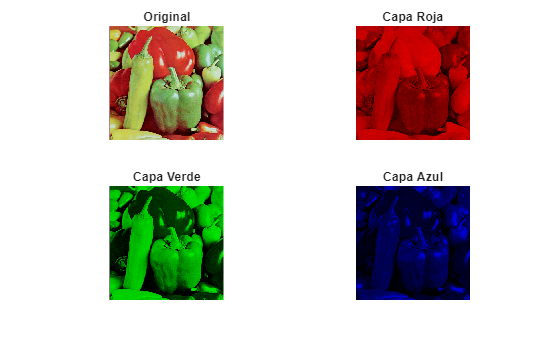

%1. Leer la imagen
img = imread('ImplementacionCompleta\Peppers.jpg');

% 2. Separar en matrices matemáticas 2D (R, G, B)
rojo = img(:,:,1);
verde = img(:,:,2);
azul = img(:,:,3);

% 3. Crear los "Lienzos" a color (Imágenes 3D completas)
% Creamos matrices negras (ceros) del mismo tamaño que la foto original.
% Es vital que sean tipo 'uint8' para que MATLAB las trate como colores reales.
[filas, columnas, ~] = size(img);
lienzo_negro = zeros(filas, columnas, 3, 'uint8');

% Capa Roja visual: Solo tiene luz en el canal 1
img_roja = lienzo_negro;
img_roja(:,:,1) = rojo;

% Capa Verde visual: Solo tiene luz en el canal 2
img_verde = lienzo_negro;
img_verde(:,:,2) = verde;

% Capa Azul visual: Solo tiene luz en el canal 3
img_azul = lienzo_negro;
img_azul(:,:,3) = azul;

% 4. Visualizar las capas en sus colores
figure;
subplot(2,2,1); imshow(img);       title('Original')
subplot(2,2,2); imshow(img_roja);  title('Capa Roja')
subplot(2,2,3); imshow(img_verde); title('Capa Verde')
subplot(2,2,4); imshow(img_azul);  title('Capa Azul')

# Encriptacion Imagen creada 

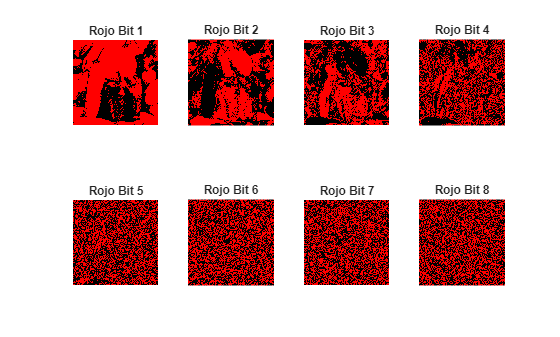


%% 1. Obtener planos de bits para los 3 canales
[filas, columnas] = size(rojo);

% Preasignamos memoria como 'logical' para máxima velocidad
rojo_bin  = zeros(filas, columnas, 8, 'logical');
verde_bin = zeros(filas, columnas, 8, 'logical');
azul_bin  = zeros(filas, columnas, 8, 'logical');

for k = 1:8
    rojo_bin(:,:,k)  = bitget(rojo, 9-k);
    verde_bin(:,:,k) = bitget(verde, 9-k);
    azul_bin(:,:,k)  = bitget(azul, 9-k);
end

%% ===== VISUALIZAR PLANOS DE BITS ORIGINALES (Antes de encriptar) =====

% Definir los "Filtros de Color" (Colormaps)
mapa_rojo  = [0 0 0; 1 0 0];
mapa_verde = [0 0 0; 0 1 0];
mapa_azul  = [0 0 0; 0 0 1];

% 1. Visualizar ROJO ORIGINAL
figure('Name', 'Planos Originales (ROJO)');
for k = 1:8
    subplot(2,4,k)
    imshow(rojo_bin(:,:,k))
    colormap(gca, mapa_rojo)
    title(['Rojo Bit ', num2str(k)])
end

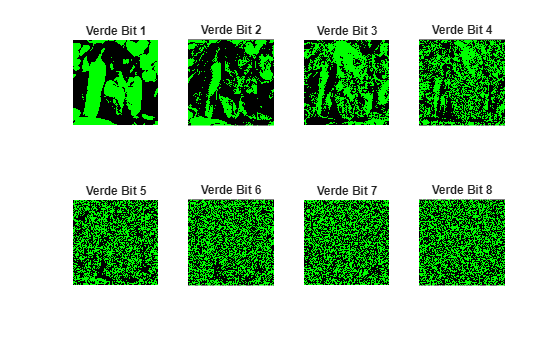


% 2. Visualizar VERDE ORIGINAL
figure('Name', 'Planos Originales (VERDE)');
for k = 1:8
    subplot(2,4,k)
    imshow(verde_bin(:,:,k))
    colormap(gca, mapa_verde)
    title(['Verde Bit ', num2str(k)])
end

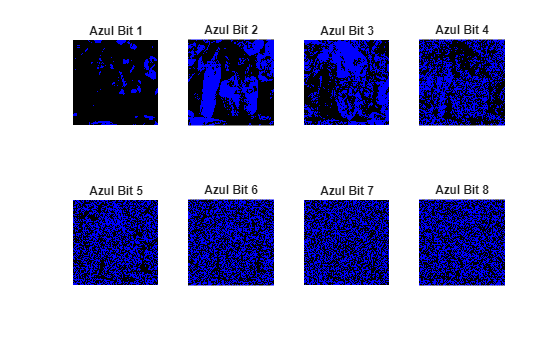


% 3. Visualizar AZUL ORIGINAL
figure('Name', 'Planos Originales (AZUL)');
for k = 1:8
    subplot(2,4,k)
    imshow(azul_bin(:,:,k))
    colormap(gca, mapa_azul)
    title(['Azul Bit ', num2str(k)])
end

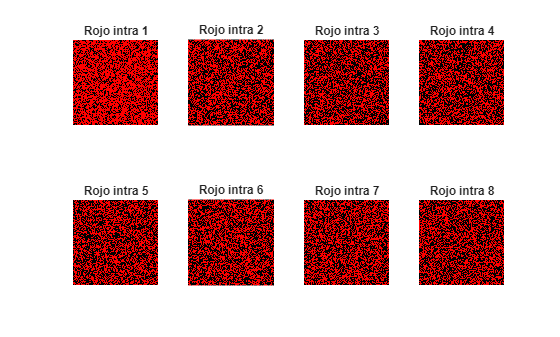


%% ===== PERMUTACIÓN INTRA BIT =====
% (El código que tenías sigue exactamente igual aquí abajo)

% Semillas del mapa logístico
seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

% Preasignar matrices resultantes
rojo_perm  = zeros(size(rojo_bin), 'logical');
verde_perm = zeros(size(verde_bin), 'logical');
azul_perm  = zeros(size(azul_bin), 'logical');

circuits = cell(1,8);

% Encriptamos las 3 capas en el mismo ciclo
for k = 1:8
    % --- Encriptar ROJO ---
    bp_R = rojo_bin(:,:,k);
    [bp_perm_R, Gmask, ~] = intraBitPermutation(bp_R, seeds(k));
    rojo_perm(:,:,k) = bp_perm_R;
    
    % Guardamos el circuito de la capa roja (como referencia)
    circuits{k} = buildIntraBitCircuit(Gmask);
    
    % --- Encriptar VERDE ---
    bp_G = verde_bin(:,:,k);
    [bp_perm_G, ~, ~] = intraBitPermutation(bp_G, seeds(k));
    verde_perm(:,:,k) = bp_perm_G;
    
    % --- Encriptar AZUL ---
    bp_B = azul_bin(:,:,k);
    [bp_perm_B, ~, ~] = intraBitPermutation(bp_B, seeds(k));
    azul_perm(:,:,k) = bp_perm_B;
end

%% ===== VISUALIZAR PLANOS PERMUTADOS EN SUS COLORES =====

% Definir los "Filtros de Color" (Colormaps)
% Fila 1: Valor lógico 0 (Negro = [0 0 0])
% Fila 2: Valor lógico 1 (Color Puro = [R G B])
mapa_rojo  = [0 0 0; 1 0 0];
mapa_verde = [0 0 0; 0 1 0];
mapa_azul  = [0 0 0; 0 0 1];

% 1. Visualizar ROJO
figure('Name', 'Planos Permutados (ROJO)');
for k = 1:8
    subplot(2,4,k)
    imshow(rojo_perm(:,:,k))
    colormap(gca, mapa_rojo) % Aplica el filtro rojo solo a este cuadro
    title(['Rojo intra ', num2str(k)])
end

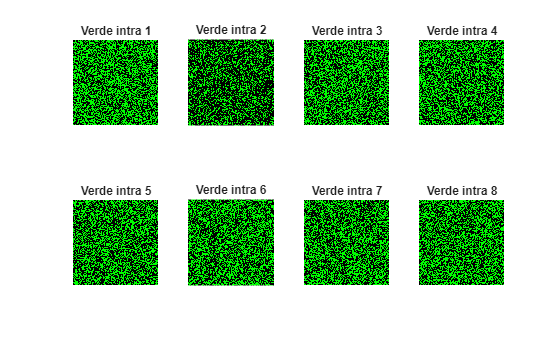


% 2. Visualizar VERDE
figure('Name', 'Planos Permutados (VERDE)');
for k = 1:8
    subplot(2,4,k)
    imshow(verde_perm(:,:,k))
    colormap(gca, mapa_verde) % Aplica el filtro verde
    title(['Verde intra ', num2str(k)])
end

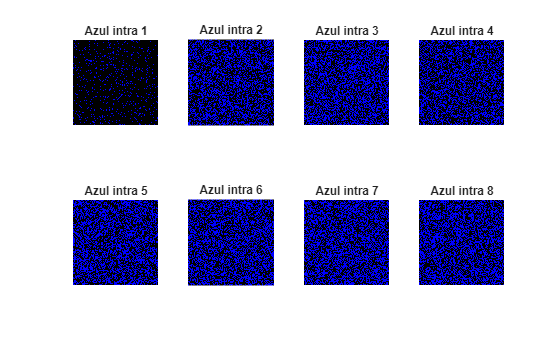


% 3. Visualizar AZUL
figure('Name', 'Planos Permutados (AZUL)');
for k = 1:8
    subplot(2,4,k)
    imshow(azul_perm(:,:,k))
    colormap(gca, mapa_azul) % Aplica el filtro azul
    title(['Azul intra ', num2str(k)])
end

## Interbit

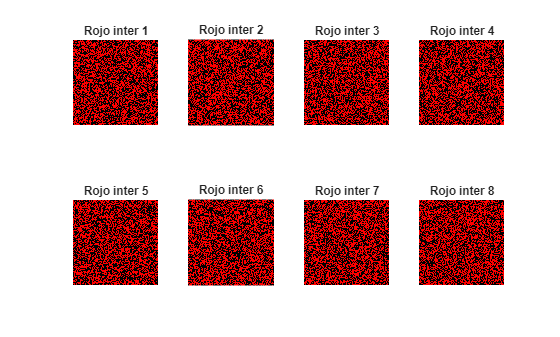


% ===== PERMUTACIÓN INTER BIT (Para los 3 canales) =====

seed_inter = 0.73;

% Si tu función solo devuelve 2 cosas, hazlo así:
[rojo_inter, order_inter] = interBitPermutation(rojo_perm, seed_inter);
[verde_inter, ~]          = interBitPermutation(verde_perm, seed_inter);
[azul_inter, ~]           = interBitPermutation(azul_perm, seed_inter);

%% ===== VISUALIZAR PLANOS DESPUÉS DE INTER-BIT =====

% Los Colormaps ya deberían estar en memoria, pero si ejecutas por bloques
% es buena idea volverlos a definir por si acaso.
mapa_rojo  = [0 0 0; 1 0 0];
mapa_verde = [0 0 0; 0 1 0];
mapa_azul  = [0 0 0; 0 0 1];

% 1. Visualizar ROJO Inter-Bit
figure('Name', 'Planos Inter-Bit (ROJO)');
for k = 1:8
    subplot(2,4,k)
    imshow(rojo_inter(:,:,k))
    colormap(gca, mapa_rojo)
    title(['Rojo inter ', num2str(k)])
end

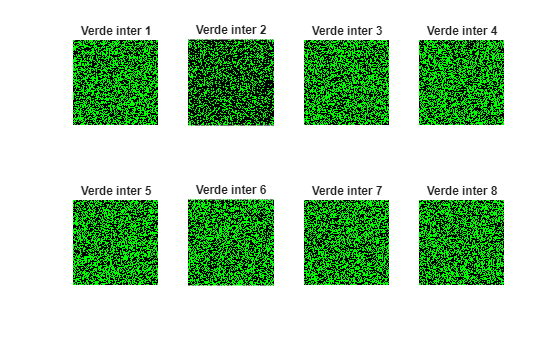


% 2. Visualizar VERDE Inter-Bit
figure('Name', 'Planos Inter-Bit (VERDE)');
for k = 1:8
    subplot(2,4,k)
    imshow(verde_inter(:,:,k))
    colormap(gca, mapa_verde)
    title(['Verde inter ', num2str(k)])
end

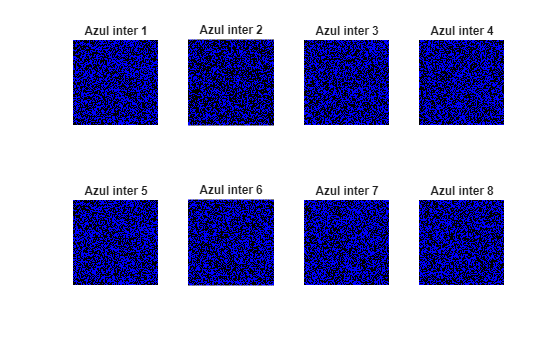


% 3. Visualizar AZUL Inter-Bit
figure('Name', 'Planos Inter-Bit (AZUL)');
for k = 1:8
    subplot(2,4,k)
    imshow(azul_inter(:,:,k))
    colormap(gca, mapa_azul)
    title(['Azul inter ', num2str(k)])
end

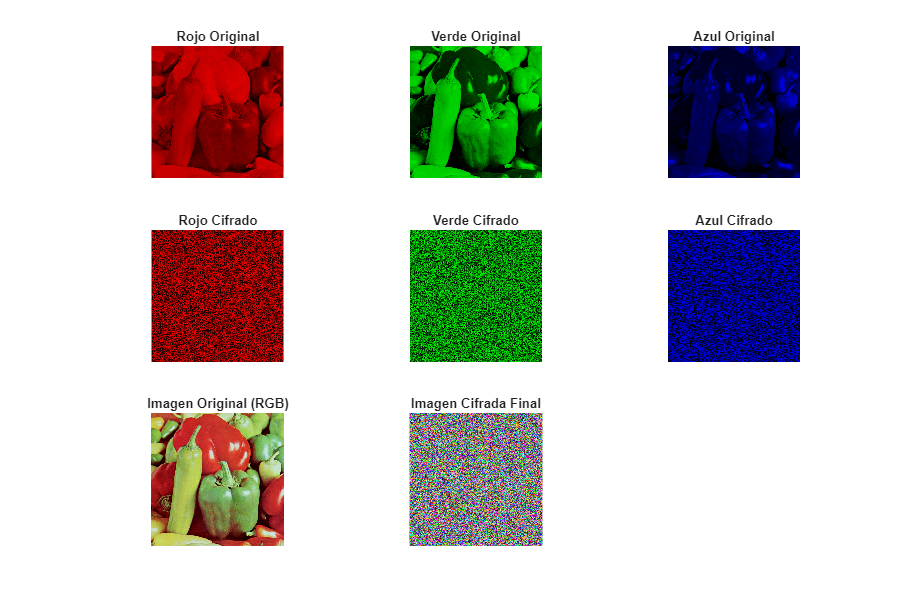


%% ===== RECONSTRUCCIÓN DE LOS 3 CANALES =====
% (Aquí va tu código de reconstrucción con bitset que te di antes)
R_reconstruido = zeros(filas, columnas, 'uint8');
G_reconstruido = zeros(filas, columnas, 'uint8');
B_reconstruido = zeros(filas, columnas, 'uint8');
for k = 1:8
    posicion_bit = 9 - k; 
    R_reconstruido = bitset(R_reconstruido, posicion_bit, rojo_inter(:,:,k));
    G_reconstruido = bitset(G_reconstruido, posicion_bit, verde_inter(:,:,k));
    B_reconstruido = bitset(B_reconstruido, posicion_bit, azul_inter(:,:,k));
end

%% ===== DIFUSIÓN CAÓTICA =====
seed_diff = 0.81;

R_cifrado = chaoticDiffusion(R_reconstruido, seed_diff);
G_cifrado = chaoticDiffusion(G_reconstruido, seed_diff);
B_cifrado = chaoticDiffusion(B_reconstruido, seed_diff);

% Unificar la imagen final
img_cifrada_final = cat(3, R_cifrado, G_cifrado, B_cifrado);


%% ===== VISUALIZACIÓN: COMPARATIVA CANAL POR CANAL =====

% Crear lienzos negros en RGB para poder pintar cada canal en su color
lienzo_negro = zeros(filas, columnas, 3, 'uint8');

% Preparar visuales originales en color
R_orig_vis = lienzo_negro; R_orig_vis(:,:,1) = rojo;
G_orig_vis = lienzo_negro; G_orig_vis(:,:,2) = verde;
B_orig_vis = lienzo_negro; B_orig_vis(:,:,3) = azul;

% Preparar visuales cifradas en color
R_cifr_vis = lienzo_negro; R_cifr_vis(:,:,1) = R_cifrado;
G_cifr_vis = lienzo_negro; G_cifr_vis(:,:,2) = G_cifrado;
B_cifr_vis = lienzo_negro; B_cifr_vis(:,:,3) = B_cifrado;

figure('Name', 'Comparativa de Encriptación por Canales', 'Position', [100 100 1200 800]);

% --- Fila 1: Imágenes Originales separadas por color ---
subplot(3,3,1); imshow(R_orig_vis); title('Rojo Original');
subplot(3,3,2); imshow(G_orig_vis); title('Verde Original');
subplot(3,3,3); imshow(B_orig_vis); title('Azul Original');

% --- Fila 2: Imágenes Cifradas separadas por color ---
subplot(3,3,4); imshow(R_cifr_vis); title('Rojo Cifrado');
subplot(3,3,5); imshow(G_cifr_vis); title('Verde Cifrado');
subplot(3,3,6); imshow(B_cifr_vis); title('Azul Cifrado');

% --- Fila 3: Imagen Compuesta Total ---
subplot(3,3,7); imshow(img); title('Imagen Original (RGB)');
subplot(3,3,8); imshow(img_cifrada_final); title('Imagen Cifrada Final (RGB)');

% Calculamos la entropía (Opcional, pero da caché académico)
% Una imagen bien cifrada tiene entropía cercana a 8.

title(['Imagen Cifrada Final']);

# Difusion inversa



function img = inverseChaoticDiffusion(img_diff, seed)
    [filas, columnas] = size(img_diff);
    N = filas * columnas;
    alpha = 3.99999;
    N0 = 1000; 

    S = logisticSequence(seed, alpha, N0, N);
    K_temp = uint8(floor(S * 256));
    K = K_temp(:);

    C = img_diff(:);
    P = zeros(N, 1, 'uint8');


    P(1) = bitxor(C(1), K(1));
    temp_xor = bitxor(C(2:end), C(1:end-1));
    P(2:N) = bitxor(temp_xor, K(2:end));

    img = reshape(P, filas, columnas);
end

# Inversa interbit


function bitplanes = inverseInterBitPermutation(bitplanes, order)

    % 1. Optimización: Obligamos a que bitplanes sea de tipo 'logical' 
    % para que el XOR sea rápido.
    bitplanes = logical(bitplanes);
    numBits = length(order); % Debería ser 8 (la cantidad de planos)

    % 2. Reversibilidad (Deshacer la Cascada)
    % En la encriptación, el loop iba de 2 hacia numBits (arriba hacia abajo).
    % Para deshacer un circuito cuántico en serie, debemos aplicar 
    % exactamente las mismas compuertas, pero de abajo hacia arriba.
    % Por eso empezamos en numBits y bajamos (-1) hasta 2.
    for m = numBits:-1:2
        % Plano de control (el mismo que se usó al encriptar)
        b_control = order(m-1); 
        % Plano objetivo (el mismo que fue modificado al encriptar)
        b_target = order(m);    
        
        % Aplicar el XOR (CNOT auto-inverso)
        bitplanes(:,:,b_target) = xor(...
            bitplanes(:,:,b_target), ...
            bitplanes(:,:,b_control) ...
        );
    end
% bitplanes = double(bitplanes);

end

# Inversa intra bit

function bp = inverseIntraBitPermutation(bp_perm, perm)

[filas, columnas] = size(bp_perm);

vector = bp_perm(:);

invperm(perm) = 1:length(perm);

vector_original = vector(invperm);

bp = reshape(vector_original, filas, columnas);

end

# Desencriptacion

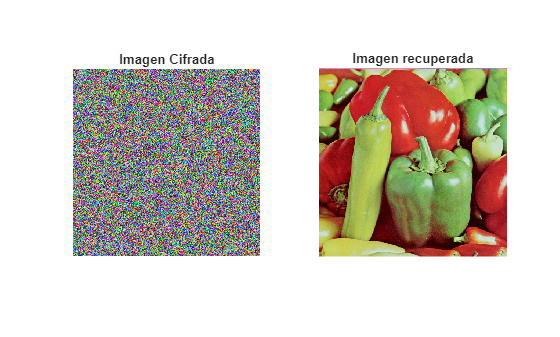

%% 1.DESHACER DIFUSIÓN CAÓTICA
% Usamos la misma semilla de difusión que en la encriptación
seed_diff = 0.81;

% Separar la imagen cifrada final en sus 3 canales de ruido
R_cifrado_rx = img_cifrada_final(:,:,1);
G_cifrado_rx = img_cifrada_final(:,:,2);
B_cifrado_rx = img_cifrada_final(:,:,3);

% Aplicar difusión inversa (Esta función es ultra rápida por la vectorización)
R_perm_recuperado = inverseChaoticDiffusion(R_cifrado_rx, seed_diff);
G_perm_recuperado = inverseChaoticDiffusion(G_cifrado_rx, seed_diff);
B_perm_recuperado = inverseChaoticDiffusion(B_cifrado_rx, seed_diff);


%% 2. ===== SEPARAR PLANOS DE BITS (Para revertir inter-bit) =====

bitplanes_R = zeros(filas, columnas, 8, 'logical');
bitplanes_G = zeros(filas, columnas, 8, 'logical');
bitplanes_B = zeros(filas, columnas, 8, 'logical');

for k = 1:8

    % lo forzamos a 'logical' porque inverseInterBit lo necesita así
    bitplanes_R(:,:,k) = logical(bitget(R_perm_recuperado, 9-k));
    bitplanes_G(:,:,k) = logical(bitget(G_perm_recuperado, 9-k));
    bitplanes_B(:,:,k) = logical(bitget(B_perm_recuperado, 9-k));
end

%% 3. DESHACER INTER-BIT
% Generamos la llave 'order' usando la semilla y la misma secuencia lógica
seed_inter = 0.73;
alpha = 3.99999;
N0 = 1000; 

S_inter = logisticSequence(seed_inter, alpha, N0, 8);
order_inter_recuperado = getPermutationFromChaos(S_inter);

% Aplicamos la cascada inversa a cada canal
bitplanes_R = inverseInterBitPermutation(bitplanes_R, order_inter_recuperado);
bitplanes_G = inverseInterBitPermutation(bitplanes_G, order_inter_recuperado);
bitplanes_B = inverseInterBitPermutation(bitplanes_B, order_inter_recuperado);

%% 4. ===== DESHACER INTRA-BIT =====
seeds = [0.5 0.52 0.53 0.6 0.37 0.46 0.38 0.61];

for k = 1:8
    % Generamos la llave de permutación para este bit-plane
    S_intra = logisticSequence(seeds(k), alpha, N0, filas*columnas);
    perm_recuperada = getPermutationFromChaos(S_intra);
    
    % Aplicamos la función inversa (que usa la indexación inversa de MATLAB)
    bitplanes_R(:,:,k) = inverseIntraBitPermutation(bitplanes_R(:,:,k), perm_recuperada);
    bitplanes_G(:,:,k) = inverseIntraBitPermutation(bitplanes_G(:,:,k), perm_recuperada);
    bitplanes_B(:,:,k) = inverseIntraBitPermutation(bitplanes_B(:,:,k), perm_recuperada);
end

%% 5.RECONSTRUIR LA IMAGEN FINAL

img_original_R = zeros(filas, columnas, 'uint8');
img_original_G = zeros(filas, columnas, 'uint8');
img_original_B = zeros(filas, columnas, 'uint8');

for k = 1:8
    posicion_bit = 9 - k; 
    img_original_R = bitset(img_original_R, posicion_bit, bitplanes_R(:,:,k));
    img_original_G = bitset(img_original_G, posicion_bit, bitplanes_G(:,:,k));
    img_original_B = bitset(img_original_B, posicion_bit, bitplanes_B(:,:,k));
end

% Unir los canales desencriptados
img_desencriptada = cat(3, img_original_R, img_original_G, img_original_B);

%% VISUALIZACIÓN FINAL
figure('Name', 'Proceso Finalizado con Éxito');
subplot(1,2,1); imshow(img_cifrada_final); title('Imagen Cifrada');
subplot(1,2,2); imshow(img_desencriptada); title('Imagen recuperada');


tiempofinal = toc;
fprintf('El tiempo total fue de: %.4f segundos\n', tiempofinal);

El tiempo total fue de: 29.6863 segundos



 %Calculo de perdida de información:

diferencia = sum(abs(img(:) - img_desencriptada(:)));
if diferencia == 0
    fprintf('Validación cuántica: Las imágenes son 100%% idénticas. Diferencia = 0.\n');
else
    fprintf('Error: Hubo pérdida de información. Diferencia = %d\n', diferencia);
end

Validación cuántica: Las imágenes son 100% idénticas. Diferencia = 0.
